close("all"); clear; clc;

A = [
    -1,-4;
    4,-1
    ];

B = ones(2,1);

C = eye(2);

sys = linearSys(A,B,[],C);

ns = 100;
ts = 0.02;
tf = ns*ts;
t = linspace(0,tf,ns + 1);

params.tFinal = tf;
params.R0 = zonotope([1;0],0.1.*eye(2));
params.U = zonotope(interval(-0.05,0.05));

options.timeStep = ts;
options.zonotopeOrder = 10;
options.taylorTerms = 5;

R = reach(sys,params,options);

simOpt.points = 10;
simRes = simulateRandom(sys,params,simOpt);

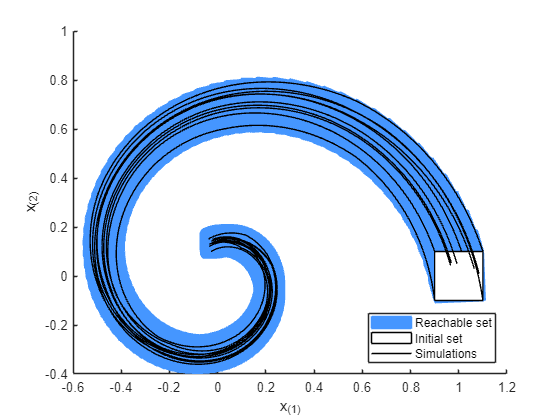

figure; hold on;
 
useCORAcolors("CORA:contDynamics")
plot(R,[1,2],'DisplayName','Reachable set')
plot(R.R0,[1,2],'DisplayName','Initial set')
plot(simRes,[1,2],'DisplayName','Simulations')

legend('Location','southeast')
xlabel('x_{(1)}')
ylabel('x_{(2)}')